% Load the first figure
fig1 = openfig('aggrfeasstair.fig');
ax1 = gca(fig1); % Get axes of figure 1
line1 = findobj(ax1, 'Type', 'Line'); % Get line object from axes 1

% Extract data from the first line
xData1 = get(line1, 'XData');
yData1 = get(line1, 'YData');

% Load the second figure
fig2 = openfig('aggrfeasstairEC90.fig');
ax2 = gca(fig2); % Get axes of figure 2
line2 = findobj(ax2, 'Type', 'Line'); % Get line object from axes 2

% Extract data from the second line
xData2 = get(line2, 'XData');
yData2 = get(line2, 'YData');

% Load the third figure
fig3 = openfig('aggrfeasstairEC45.fig');
ax3 = gca(fig3); % Get axes of figure 3
line3 = findobj(ax3, 'Type', 'Line'); % Get line object from axes 3

% Extract data from the third line
xData3 = get(line3, 'XData');
yData3 = get(line3, 'YData');

% Create a new figure
figure;

% Plot lines from the first figure
plot(xData1, yData1); % Blue line

hold on; % Hold the plot to add more lines

% Plot lines from the second figure
plot(xData2, yData2); % Red line

% Plot lines from the third figure
plot(xData3, yData3); % Green line

% Customize your plot as needed
xlabel('Reduction Ratio N');
ylabel('Feasible profiles');
xline(81,'r','N=81',LineWidth=1.5,LabelVerticalAlignment='bottom')
title('Combined Plot');
legend('EC60-150W', 'EC90-220W', 'EC45-80W');
ylim([0 49])


hold off; % Release hold on the plot

% Close the opened figures if needed
close(fig1);
close(fig2);
close(fig3);

% save figure
pathfig = 'C:\Users\u0130154\MATLAB\projects\seasize\thesis_figure';
pathpng = 'C:\Users\u0130154\OneDrive - KU Leuven\PhD\_writing\_thesis\phdthesis\chapters\actuatordesign\image';

fig=gcf

fig =   Figure (206) with properties:

      Number: 206
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


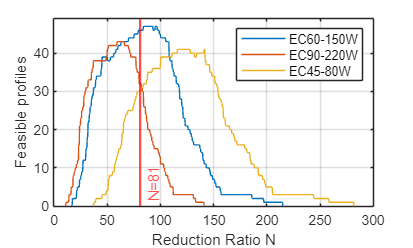


ax = gca;
grid on
fig.Units = 'inches';
fig.Position = [0, 0, 5, 3];
title('')
% Save the figure as PNG
savefig([pathfig '\aggrfeasstairAll'])
export_fig([pathpng '\aggrfeasstairAll.png'], '-png', '-r300', '-nocrop', '-transparent')